format long;

Problema 1. Conditionarea radacinilor ecuatiei de grad 2.

cond_quad(1, 1.999, 1)

ans =   47.424281920010728


cond_quad(0.999, 2, 1)

ans =   46.934164902523555


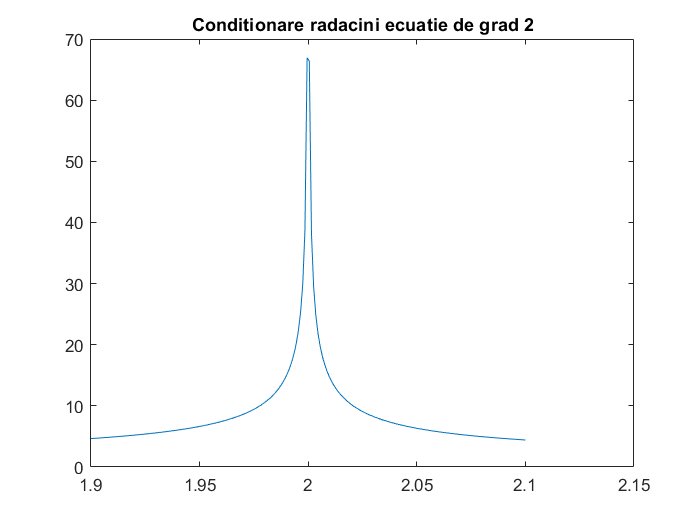

a = 1;
c = 1;
b_vals = linspace(1.9, 2.1, 200);
conds = zeros(size(b_vals));

for i = 1:length(b_vals)
    b = b_vals(i);
    conds(i) = cond_quad(a, b, c);
end

plot(b_vals, conds);
title('Conditionare radacini ecuatie de grad 2');

Alta incercare, simbolica

cond_quad_sym()

$$ans = \begin{array}{l} \left(\begin{array}{cc} \frac{2\,\left|b\right|+\sigma_{3}}{2\,\sigma_{1}}+\frac{2\,\left|a\right|\,\left|c\right|}{\sigma_{1}\,\sigma_{3}} & \frac{\sigma_{2}+2\,\left|b\right|}{2\,\sigma_{1}}+\frac{2\,\left|a\right|\,\left|c\right|}{\sigma_{2}\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\left|b^{2}-4\,a\,c\right|}\\ \sigma_{2}=\left|\sqrt{b^{2}-4\,a\,c}-b\right|\\ \sigma_{3}=\left|b+\sqrt{b^{2}-4\,a\,c}\right| \end{array}$$

% Evaluare a expresiei de mai sus
cond_quad_eval(1, 1.999, 1)

ans =    63.2376   63.2376


cond_quad_eval(0.999, 2, 1)

ans =   63.245553203367564  63.245553203367564


cond_quad_eval(1, 1e8, 1) % Nu cred ca e bine aici

ans =    2.000000000000000   2.342177280000000


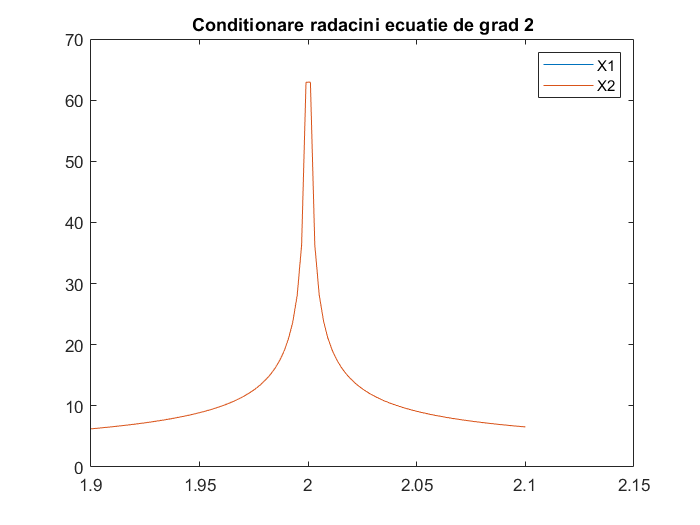

a = 1;
c = 1;
b_vals = linspace(1.9, 2.1, 100);
conds1 = zeros(size(b_vals));
conds2 = zeros(size(b_vals));

for i = 1:length(b_vals)
    b = b_vals(i);
    cr = cond_quad_eval(a, b, c);
    conds1(i) = cr(1);
    conds2(i) = cr(2);
end

plot(b_vals, conds1, b_vals, conds2);
title('Conditionare radacini ecuatie de grad 2');
legend('X1', 'X2');

Problema 2. Rutina de rezolvare a ecuatiei de grad 2.

% Caz normal
rt = stable_quadratic_solver(2, 5, 2);
r1 = [rt(2) ; rt(1)]

r1 =   -2.000000000000000
  -0.500000000000000


r2 = roots([2, 5, 2])

r2 =   -2.000000000000000
  -0.500000000000000



err = norm(r1 - r2) / norm(r2)

err =      0


% Caz in care b^2 aprox. egal cu 4*a*c
rt = stable_quadratic_solver(2 - 1e-10, 4, 2);
r1 = [rt(2) ; rt(1)]

r1 =   -1.000007071118105
  -0.999992928981895


r2 = roots([2 - 1e-10, 4, 2])

r2 =   -1.000007071118105
  -0.999992928981895



err = norm(r1 - r2) / norm(r2)

err =      1.755416734156694e-16


rt = stable_quadratic_solver(vpa(1) - vpa(1e-16), 1, 1/4); % 1 - 1e-16 simplu isi pierde precizia cand se transforma in vpa in procedura
r1 = [eval(rt(2)); eval(rt(1))]

r1 =   -0.500000000000000
  -0.500000000000000


r2 = roots([1 - 1e-16, 1, 1/4])

r2 =   -0.500000000000000
  -0.500000000000000



err = (norm(r1 - r2) / norm(r2))

err =      0


% Caz in care b^2 >> 4*a*c si b > 0
rt = stable_quadratic_solver(2, 1e8, 3);
r1 = [rt(2) ; rt(1)]

r1 = 	1.0e+07 *

  -4.999999999999997
  -0.000000000000003


r2 = roots([2, 1e8, 3])

r2 = 	1.0e+07 *

  -4.999999999999997
  -0.000000000000003



err = norm(r1 - r2) / norm(r2)

err =      0


% Caz in care b^2 >> 4*a*c si b < 0
rt = stable_quadratic_solver(2, -1e8, 3);
r1 = rt'

r1 = 	1.0e+07 *

   4.999999999999997
   0.000000000000003


r2 = roots([2, -1e8, 3])

r2 = 	1.0e+07 *

   4.999999999999997
   0.000000000000003



err = norm(r1 - r2) / norm(r2)

err =      0


% Posibila depasire la calculul discriminantului
rt = stable_quadratic_solver(1e150, 3e200, 1e250);
r1 = [rt(2) ; rt(1)]

r1 = 	1.0e+50 *

  -2.618033988749894
  -0.381966011250105


r2 = roots([1e150, 3e200, 1e250])

r2 = 	1.0e+50 *

  -2.618033988749894
  -0.381966011250105



err = norm(r1 - r2) / norm(r2)

err =      1.962503745843583e-17
